%% 2/20/2020: Imports new split digital and analog .CSV files output from phoLabjackControllerSoftware and combines them into a single CSV

addpath(genpath('HelperFunctions'));
%default_folder = 'E:\EventData\EventData\BB02\experiment_00\cohort_00\animal_02';
% curr_bbID = '02';
%curr_bbID = '04';
% default_folder = 'E:\EventData\EventData\BB02\experiment_00\cohort_00\animal_02';

% bbIDs = {'02','04','06','09','12','14','15','16'}
% 
% for i=1:length(bbIDs)
%     curr_bbID = bbIDs{i};
%     curr_folder = ['E:\EventData\EventData\BB', curr_bbID, '\experiment_00\cohort_00\animal_', curr_bbID];
%    
%     if ~exist('foundCSVFiles','var')
%         rootSearchPath = uigetdir('Select the folder containing the CSV data');
%         if isequal(rootSearchPath,0)
%             disp('ERROR: You must choose a root directory.')
%             return
%         end
%     else
%         rootSearchPath = curr_folder;
%     end
% 
%     % Find the CSV Files in the childSearchPaths
%     [foundCSVFiles, foundDigitalCSVFiles, foundAnalogCSVFiles] = findCSVFiles({rootSearchPath});
%     [writtenOutputFilePath_digital] = BuildCombinedCSV(rootSearchPath, foundDigitalCSVFiles);
%     [writtenOutputFilePath_analog] = BuildCombinedCSV(rootSearchPath, foundAnalogCSVFiles);
% end
% 


combined_analog_file_path = 'E:\EventData\EventData\BB02\experiment_00\cohort_00\animal_02\Combined\out_file_analog_s470019538_1581354045076-1581709366755_8_Combined.csv'

combined_analog_file_path = 'E:\EventData\EventData\BB02\experiment_00\cohort_00\animal_02\Combined\out_file_analog_s470019538_1581354045076-1581709366755_8_Combined.csv'

% ImportPhoLabjackServerAnalogEventsCsvFile(combined_analog_file_path)

varNames = {'RunningWheel'};
loadedLabjackData = importPhoLabjackServerAnalogEventsCsvFileHelper(combined_analog_file_path);

outputDateTimes = datetime(loadedLabjackData.milliseconds_since_epoch, 'convertFrom','epochtime','TicksPerSecond',1000);
outputDateTimes = outputDateTimes - hours(4); % to translate from GMT to Michigan timezone


numeric_runningWheel_min = min(loadedLabjackData.AIN0)

numeric_runningWheel_min = 0.0115

numeric_runningWheel_max = max(loadedLabjackData.AIN0)

numeric_runningWheel_max = 5.0089


% Normalize to percent rotation:
loadedLabjackData.PercentWheelRotation = (loadedLabjackData.AIN0./numeric_runningWheel_max);


% Differences:
% test = diff(loadedLabjackData.PercentWheelRotation);
loadedLabjackData.PercentWheelDifference = [0; diff(loadedLabjackData.PercentWheelRotation)];
% caldiff(outputDateTimes);

% the standard .csv's imported by TestScript have inputs like '{3643827012.79100}'
% labjackData.milliseconds_since_epoch contains: {1561753286966.00}
loadedLabjackData.timestamp = outputDateTimes;
%loadedLabjackData.timeDelta = [0; caldiff(loadedLabjackData.timestamp)];
loadedLabjackData.timeDelta = [0; diff(loadedLabjackData.timestamp)];
% workingArray = [loadedLabjackData.PercentWheelRotation]
% diff(loadedLabjackData.PercentWheelRotation)
%diffTable = diff(loadedLabjackData);


## TODO: Add zero-displacement timestamps approx 3-5 seconds after a logged event unless another event occurs. This signifies that the animal has stopped.

% Find Places where the loadedLabjackData.timeDelta > 5 seconds, these mark the start of a new running session.
loadedLabjackData.timeDeltaSeconds = seconds(loadedLabjackData.timeDelta);
transitionIndexes = (loadedLabjackData.timeDeltaSeconds > 5.0);

%[transitionIndexes(2:end)


for i=1:length(loadedLabjackData.timestamp)
    currentTimeStamp
end

loadedLabjackData.WheelPercentVelocity = [0.0; (loadedLabjackData.PercentWheelDifference(2:end) ./ seconds(loadedLabjackData.timeDelta(2:end)))];

t1 = datetime(2020,2,15,0,0,0);
t2 = datetime(2020,2,17,0,0,0);

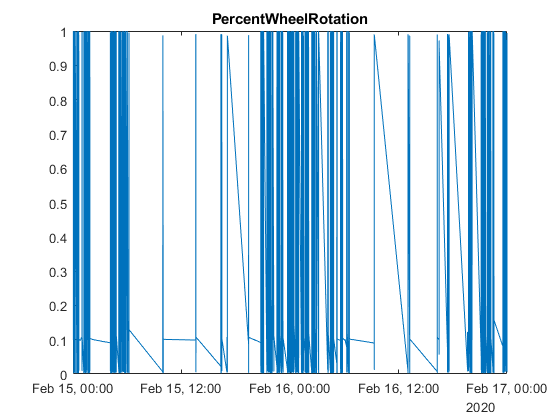

plot(loadedLabjackData.timestamp, loadedLabjackData.PercentWheelRotation)
title('PercentWheelRotation')
xlim([t1, t2])

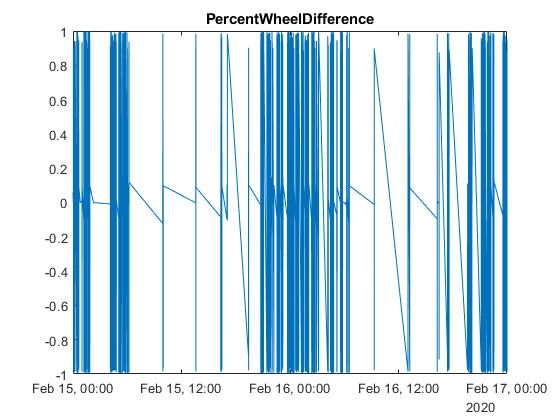

plot(loadedLabjackData.timestamp, loadedLabjackData.PercentWheelDifference)
title('PercentWheelDifference')
xlim([t1, t2])

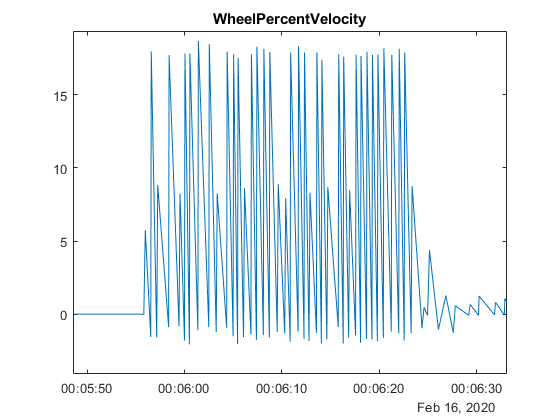

plot(loadedLabjackData.timestamp, loadedLabjackData.WheelPercentVelocity)
title('WheelPercentVelocity')
xlim([t1, t2])